Imágen baja exposición

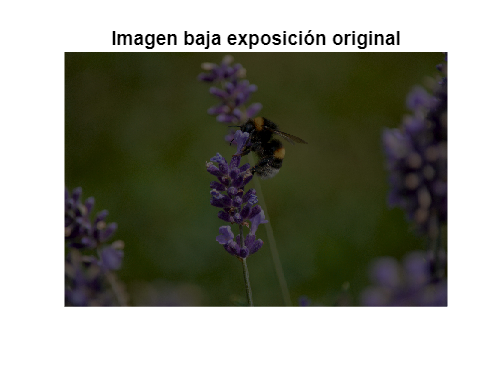

%Leer imagen
imagen_rgb = imread("baja_exposicion.jpg");
imshow(imagen_rgb);
title("Imagen baja exposición original")

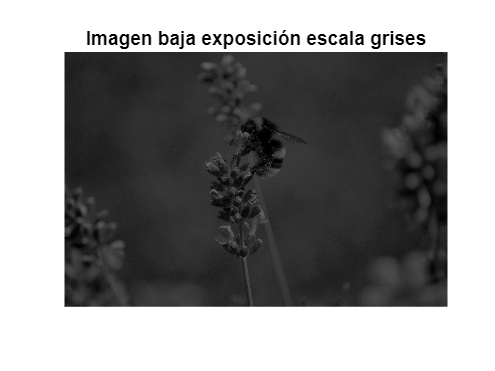


%Convertir a un solo plan RGB (escala de grises)
imagen = rgb2gray(imagen_rgb);
figure
imshow(imagen)
title("Imagen baja exposición escala grises")

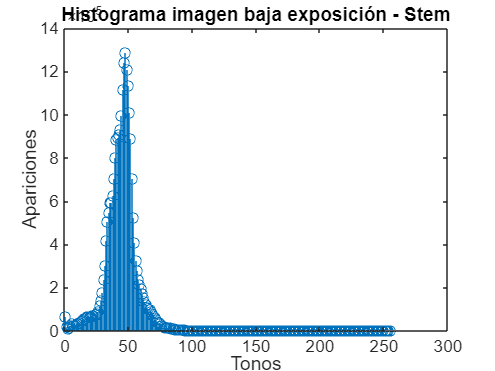


%Crear matriz para colores
colores = zeros(255,1);

%Saber la dimensión de la imagen
[x, y] = size(imagen);

%Contar pixeles
for alto = 1:y
    for ancho = 1:x
        tono = imagen(ancho,alto);
        colores(tono+1)= colores(tono+1) + 1;
    end
end

%Graficar Histograma
stem(1:255, colores);
title("Histograma imagen baja exposición - Stem")
xlabel("Tonos");
ylabel("Apariciones");

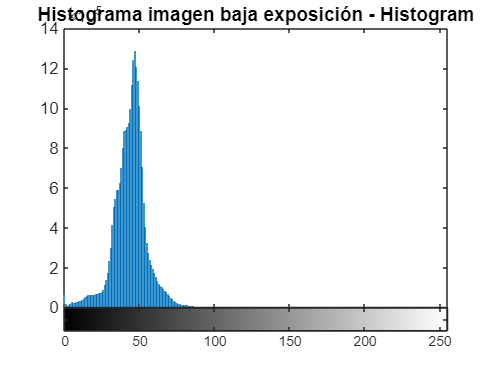


imhist(imagen)
ylim([0 1400000]);
title("Histograma imagen baja exposición - Histogram")

Imágen alta exposición

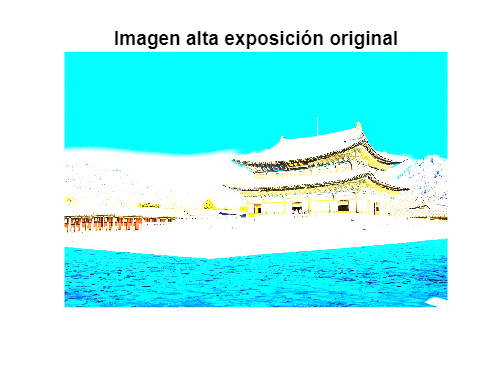

%Leer imagen
imagen_rgb = imread("alta_exposicion.jpg");
imshow(imagen_rgb);
title("Imagen alta exposición original")

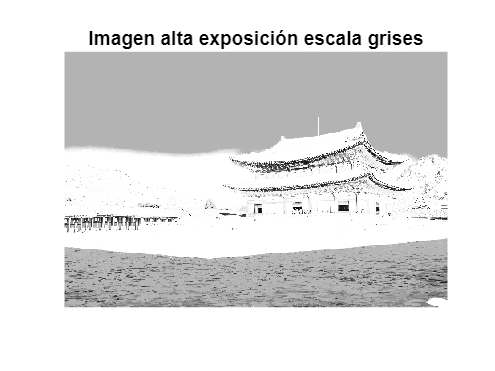


%Convertir a un solo plan RGB (escala de grises)
imagen = rgb2gray(imagen_rgb);
figure
imshow(imagen)
title("Imagen alta exposición escala grises")

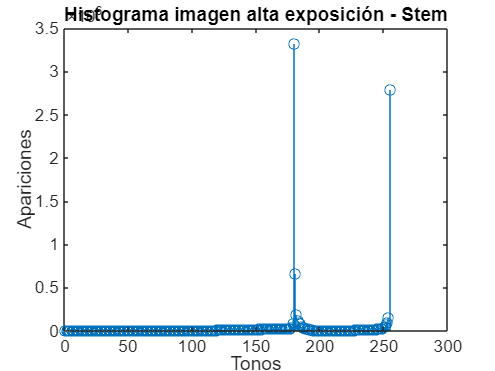


%Crear matriz para colores
colores = zeros(255,1);

%Saber la dimensión de la imagen
[x, y] = size(imagen);

%Contar pixeles
for alto = 1:y
    for ancho = 1:x
        tono = imagen(ancho,alto);
        colores(tono+1)= colores(tono+1) + 1;
    end
end

%Graficar Histograma
stem(1:255, colores);
title("Histograma imagen alta exposición - Stem")
xlabel("Tonos");
ylabel("Apariciones");

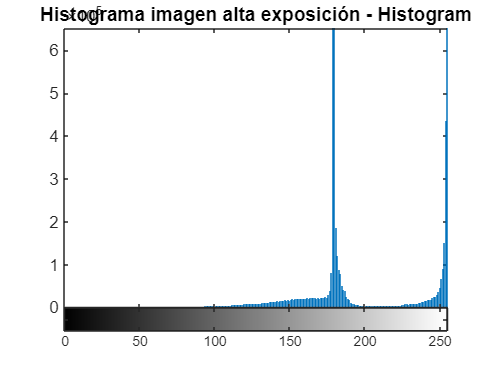


imhist(imagen)
title("Histograma imagen alta exposición - Histogram")

Imágen buena exposición

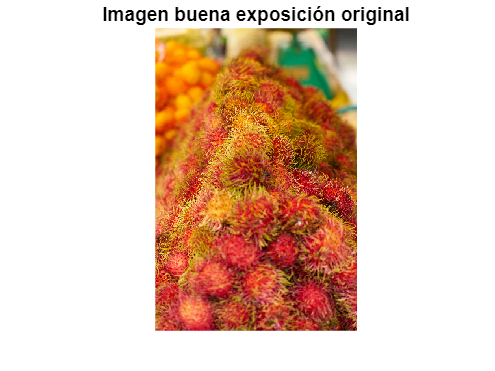

%Leer imagen
imagen_rgb = imread("buena_exposicion.jpg");
imshow(imagen_rgb);
title("Imagen buena exposición original")

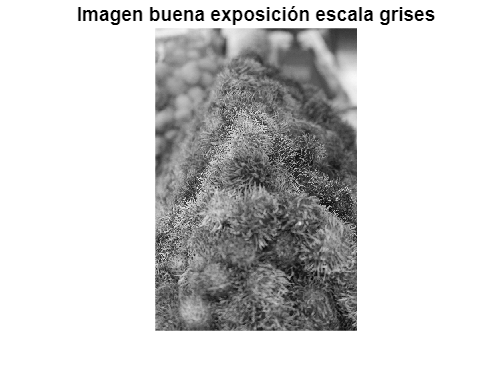


%Convertir a un solo plan RGB (escala de grises)
imagen = rgb2gray(imagen_rgb);
figure
imshow(imagen)
title("Imagen buena exposición escala grises")

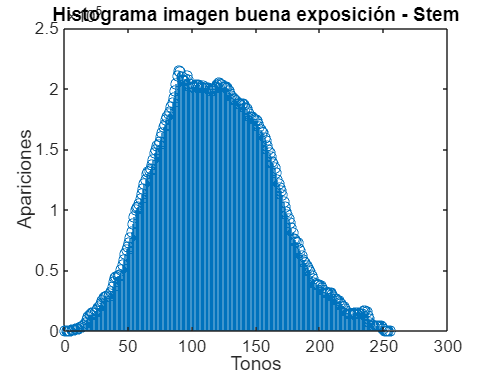


%Crear matriz para colores
colores = zeros(255,1);

%Saber la dimensión de la imagen
[x, y] = size(imagen);

%Contar pixeles
for alto = 1:y
    for ancho = 1:x
        tono = imagen(ancho,alto);
        %Verificar que tono esté dentro del rango
        %if tono >= 0 && tono < 256
            colores(tono+1)= colores(tono+1) + 1;
        %end
    end
end

%Graficar Histograma
stem(1:255, colores);
title("Histograma imagen buena exposición - Stem")
xlabel("Tonos");
ylabel("Apariciones");

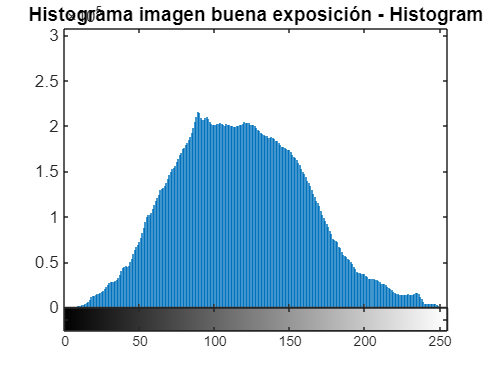


imhist(imagen)
title("Histograma imagen buena exposición - Histogram")